# MODELO DE DIAGNÓSTICO


close all; clc; clearvars;


## PREPROCESAMIENTO 

En este apartado se han eliminado de la base de datos las imagenes incorrectamente segmentadas. En total, se ha eliminado el 15% de la base de datos. 

T = readtable('Caracteristicas_MODELO.csv')

T = 1379×54 table
          image           Entropia_CR    Entropia_CV    Entropia_CA    Area_Copa    Diametro_Copa_MAX    Diametro_Copa_MIN    Area_Disco    Diametro_Disco_MAX    Diametro_Disco_MIN    C_DRatio    contrast_red    homogeneity_red    correlation_red    energy_red    contrast_green    homogeneity_green    correlation_green    energy_green    contrast_blue    homogeneity_blue    correlation_blue    energy_blue    mean_wavelet_1    mean_wavelet_2    mean_wavelet_3    mean_wavelet_4    mean_wavelet_5    

% filas_a_eliminar = T.C_DRatio == 0;
numeros_a_eliminar = {'0002','0003','0004','0026','0027','0028','0036','0037','0043','0057','0060','0062','0071','0075','0076','0080','0097','0122','0125','0137','0135','0152','0168','0173','0180','0197','0198','0213','0214','0216','0217','0219','0221','0237','0238','0256','0257','0269','0273','0289','0298','0306','0316','0319','0332','0334','0339','0340','0348','0351','0383','0389','0399','0422','0425','0438','0450','0473','0482','0496','0504','0518','0522','0561','0572','0590','0594','0595','0600','0613','0633','0636','0645','0671','0675','0708','0715','0742','0753','0759','0778','0779','0781','0783','0791','0792','0795','0800','0807','0816','0822','0827','0829','0830','0832','0842','0852','0869','0902','0904','0905','0913','0922','0925','0926','0927','0937','0938','0941','0950','0961','0969','0972','0977','0979','0989','0990','0991','1002','1027','1041','1045','1053','1061','1075','1076','1080','1082','1084','1088','1100','1105','1117','1133','1152','1151','1163','1164','1169','1174','1175','1191','1193','1200','1206','1208','1223','1232','1244','1251','1254','1263','1266','1268','1269','1270','1277','1288','1300','1305','1306','1307','1309','1314','1318','1330','1332','1340','1345','1350','1352','1356','1360','1372','1374','1378','1381','1382','1390','1391','1402','1406','1420','1427','1430','1443','1446','1455','1465','1466','1475','1502','1503','1507','1535','1532','1542','1545','1551','1561','1564','1567','0265','0755','0862','0976','1020','1098','1317','1482','1537','1568'};
Pocertaje_eliminado=round(size(numeros_a_eliminar,2)*100/height(T))

Pocertaje_eliminado = 15


nombres_a_eliminar = strcat('image_', numeros_a_eliminar, '.jpg');


nombres_a_eliminar = cellstr(nombres_a_eliminar);

filas_a_eliminar = ismember(T.image, nombres_a_eliminar);

T(filas_a_eliminar, :) = [];

writetable(T, 'Caracteristicas_MODELO_actualizado.csv');


### **Desbalance de la variable glaucoma**

En la siguiente sección se ha mostrado el desbalance de la variable glaucoma. Al haber un desbalance mayoritario en torno a "No glaucoma", se han eliminado varias imagenes de esta clase, consiguiendo así una base de datos balanceada. Las imagenes eliminadas han sido guardadas en un .csv. 

T=readtable("Caracteristicas_MODELO_actualizado.csv")

T = 1167×54 table
          image           Entropia_CR    Entropia_CV    Entropia_CA    Area_Copa    Diametro_Copa_MAX    Diametro_Copa_MIN    Area_Disco    Diametro_Disco_MAX    Diametro_Disco_MIN    C_DRatio    contrast_red    homogeneity_red    correlation_red    energy_red    contrast_green    homogeneity_green    correlation_green    energy_green    contrast_blue    homogeneity_blue    correlation_blue    energy_blue    mean_wavelet_1    mean_wavelet_2    mean_wavelet_3    mean_wavelet_4    mean_wavelet_5    

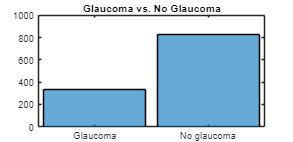


T.glaucoma = cellstr(num2str(T.glaucoma));

for i = 1:height(T)
    if T.glaucoma{i} == '1'
        T.glaucoma{i} = 'Glaucoma';
    elseif T.glaucoma{i} == '0'
        T.glaucoma{i} = 'No glaucoma';
    end
end

X = T{:, 2:end-1};
Y = T.glaucoma;

figure('Position', [0 0 350 170]);
histogram(categorical(Y))
title('Glaucoma vs. No Glaucoma')


class_no_glaucoma = T(T.glaucoma == "No glaucoma", :); % Clase mayoritaria
class_glaucoma = T(T.glaucoma == "Glaucoma", :); % Clase minoritaria

num_class_glaucoma = height(class_glaucoma); % Número de muestras en la clase minoritaria
random_indices = randperm(height(class_no_glaucoma), num_class_glaucoma); % Índices aleatorios
class_no_glaucoma_downsampled = class_no_glaucoma(random_indices, :); % Submuestrear la clase mayoritaria

% Guardar los índices de las filas eliminadas
indices_eliminados = setdiff(1:height(class_no_glaucoma), random_indices);
% Guardar los índices eliminados en un archivo CSV para referencia
writematrix(indices_eliminados', 'indices_eliminados.csv');

% Combinar las clases
balanced_data = [class_no_glaucoma_downsampled; class_glaucoma];
balanced_data = balanced_data(randperm(height(balanced_data)), :); % Mezclar aleatoriamente

writetable(balanced_data, 'Caracteristicas_BALANCED_MODELO.csv');

% Verificar el balance de clases después del submuestreo
disp('Número de muestras de cada clase (balanceado):');

Número de muestras de cada clase (balanceado):


disp(['Glaucoma: ', num2str(sum(balanced_data.glaucoma == "Glaucoma"))]);

Glaucoma: 337


disp(['No glaucoma: ', num2str(sum(balanced_data.glaucoma == "No glaucoma"))]);

No glaucoma: 337



prueba=sortrows(balanced_data.image(balanced_data.glaucoma=="Glaucoma"))

prueba = 337×1 cell array
    {'image_0005.jpg'}
    {'image_0010.jpg'}
    {'image_0016.jpg'}
    {'image_0029.jpg'}
    {'image_0032.jpg'}
    {'image_0034.jpg'}
    {'image_0044.jpg'}
    {'image_0047.jpg'}
    {'image_0051.jpg'}
    {'image_0058.jpg'}
    {'image_0059.jpg'}
    {'image_0070.jpg'}
    {'image_0072.jpg'}
    {'image_0079.jpg'}
    {'image_0084.jpg'}
    {'image_0086.jpg'}
    {'image_0090.jpg'}
    {'image_0091.jpg'}
    {'image_0092.jpg'}
    {'image_0093.jpg'}
    {'image_0102.jpg'}
    {'image_0103.jpg'}
    {'image_0106.jpg'}
    {'image_0107.jpg'}
    {'image_0110.jpg'}
    {'image_0119.jpg'}
    {'image_0121.jpg'}
    {'image_0128.jpg'}
    {'image_0141.jpg'}
    {'image_0146.jpg'}


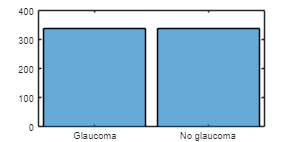


X = balanced_data{:, 2:end-1}; % Características (ajusta según las columnas de tus datos)
Y = balanced_data.glaucoma; % Etiquetas
histogram(categorical(Y))

### Correlación de variables

Se muestra la correlación completa con la base de datos balanceada. 

T=readtable('Caracteristicas_BALANCED_MODELO.csv')

T = 674×54 table
          image           Entropia_CR    Entropia_CV    Entropia_CA    Area_Copa    Diametro_Copa_MAX    Diametro_Copa_MIN    Area_Disco    Diametro_Disco_MAX    Diametro_Disco_MIN    C_DRatio    contrast_red    homogeneity_red    correlation_red    energy_red    contrast_green    homogeneity_green    correlation_green    energy_green    contrast_blue    homogeneity_blue    correlation_blue    energy_blue    mean_wavelet_1    mean_wavelet_2    mean_wavelet_3    mean_wavelet_4    mean_wavelet_5    

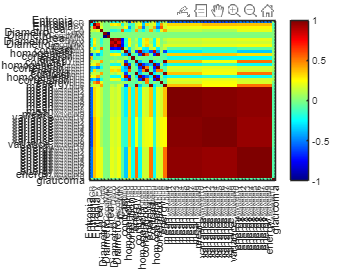

 for i = 1:height(T)
        if strcmp(T.glaucoma{i}, 'Glaucoma')
            T.glaucoma{i} = 1;
        elseif strcmp(T.glaucoma{i}, 'No glaucoma')
            T.glaucoma{i} = 0;
        end
    end
    % Convertir la columna a un array numérico
    T.glaucoma = cell2mat(T.glaucoma);
% 
variables = T.Properties.VariableNames;
X = T{:, 2:end};
R = corrcoef(X, 'Rows', 'pairwise'); % pairwise to ignore NaN values
figure;
imagesc(R); clim([-1 1]);
xticks(1:60);
xticklabels(variables(:,2:end));
yticks(1:60);
yticklabels(variables(:,2:end));
colormap(jet); colorbar;

variables = T.Properties.VariableNames;

### Procesamiento de variables

Se han eliminado varias variables para evitar redundancia y mejorar la eficiencia del modelo. 

T=readtable('Caracteristicas_BALANCED_MODELO.csv')

T = 674×54 table
          image           Entropia_CR    Entropia_CV    Entropia_CA    Area_Copa    Diametro_Copa_MAX    Diametro_Copa_MIN    Area_Disco    Diametro_Disco_MAX    Diametro_Disco_MIN    C_DRatio    contrast_red    homogeneity_red    correlation_red    energy_red    contrast_green    homogeneity_green    correlation_green    energy_green    contrast_blue    homogeneity_blue    correlation_blue    energy_blue    mean_wavelet_1    mean_wavelet_2    mean_wavelet_3    mean_wavelet_4    mean_wavelet_5    

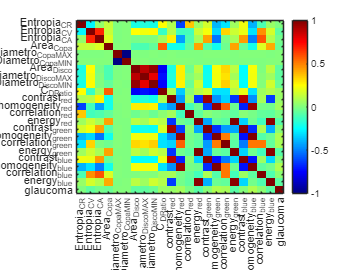

 for i = 1:height(T)
        if strcmp(T.glaucoma{i}, 'Glaucoma')
            T.glaucoma{i} = 1;
        elseif strcmp(T.glaucoma{i}, 'No glaucoma')
            T.glaucoma{i} = 0;
        end
    end
    
    T.glaucoma = cell2mat(T.glaucoma);
T.mean_wavelet_1=[];T.mean_wavelet_2=[];T.mean_wavelet_3=[];T.mean_wavelet_4=[];T.mean_wavelet_5=[];T.mean_wavelet_6=[];T.mean_wavelet_7=[];T.mean_wavelet_8=[];T.mean_wavelet_9=[];T.mean_wavelet_10=[];
T.variance_wavelet_1=[];T.variance_wavelet_2=[];T.variance_wavelet_3=[];T.variance_wavelet_4=[];T.variance_wavelet_5=[];T.variance_wavelet_6=[];T.variance_wavelet_7=[];T.variance_wavelet_8=[];T.variance_wavelet_9=[];T.variance_wavelet_10=[];
T.energy_wavelet_1=[];T.energy_wavelet_2=[];T.energy_wavelet_3=[];T.energy_wavelet_4=[];T.energy_wavelet_5=[];T.energy_wavelet_6=[];T.energy_wavelet_7=[];T.energy_wavelet_8=[];T.energy_wavelet_9=[];T.energy_wavelet_10=[];


variables = T.Properties.VariableNames;
X = T{:, 2:end};
R = corrcoef(X, 'Rows', 'pairwise'); % pairwise to ignore NaN values
figure;
imagesc(R); clim([-1 1]);
xticks(1:30);
xticklabels(variables(:,2:end));
yticks(1:30);
yticklabels(variables(:,2:end));
colormap(jet); colorbar;

variables = T.Properties.VariableNames;
writetable(T, 'Caracteristicas_BALANCED_MODELO_LIMPIO.csv');

### Comprobación de variables faltantes

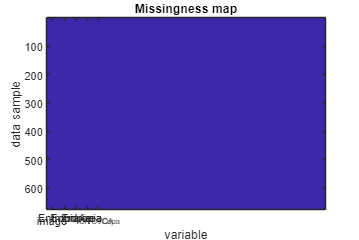

figure('Position', [0 0 600 400]);
imagesc(ismissing(T))
xticks(1:5)
xticklabels(variables);
title('Missingness map');
xlabel('variable');
ylabel('data sample');

## ENTRENAMIENTO y VALIDACIÓN DE MODELOS

close all; 
rng(4);

T=readtable('Caracteristicas_BALANCED_MODELO_LIMPIO.csv');
T.image=[];
T.glaucoma = cellstr(num2str(T.glaucoma));

for i = 1:height(T)
    if T.glaucoma{i} == '1'
        T.glaucoma{i} = 'Glaucoma';
    elseif T.glaucoma{i} == '0'
        T.glaucoma{i} = 'No glaucoma';
    end
end

### División de data

p = 0.2;
cv_out = cvpartition(T.glaucoma, 'HoldOut', p, 'Stratify', true);
T_train = T(cv_out.training, :);
T_test  = T(cv_out.test, :);

k = 10;
cv_in = cvpartition(T_train.glaucoma, 'KFold', k, 'Stratify', true);

### Entrenamiento de modelo-KNN

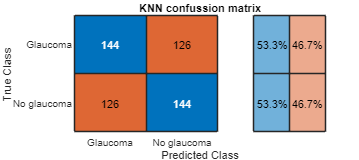

% Create cross-validated KNN model
mdl_knn = fitcknn(T_train, 'glaucoma', 'NumNeighbors', 3, 'CVPartition', cv_in);

mdl_loss = kfoldLoss(mdl_knn);  

Y_pred = kfoldPredict(mdl_knn);

sensitivity = sum(strcmp(Y_pred, 'Glaucoma') & strcmp(T_train.glaucoma, 'Glaucoma')) / sum(strcmp(T_train.glaucoma, 'Glaucoma'));
specificity = sum(strcmp(Y_pred, 'No glaucoma') & strcmp(T_train.glaucoma, 'No glaucoma')) / sum(strcmp(T_train.glaucoma, 'No glaucoma'));

% Exactitud balanceada
balanced_accuracy = (sensitivity + specificity) / 2;

results = table;
results = [results; table("Knn", mdl_loss, balanced_accuracy, 'VariableNames',{'model','loss','balanced accuracy'})];

figure('Position', [0 0 450 200]);
confusionchart(T_train.glaucoma, Y_pred, 'RowSummary','row-normalized')
title('KNN confussion matrix');

#### Optimización del modelo KNN

opt.CVPartition = cv_in;
opt.Verbose     = 0;     
opt.ShowPlots   = false; % para controlar la visualización
% Optimización del KNN
mdl_opt = fitcknn(T_train, 'glaucoma', 'OptimizeHyperparameters', 'auto', ...
    'HyperparameterOptimizationOptions', opt);

% Obtener los mejores valores de los hiperparámetros
best_values = mdl_opt.HyperparameterOptimizationResults.bestPoint;

% Reentrenamiento del modelo final
n_neighbors = best_values.NumNeighbors

n_neighbors = 22

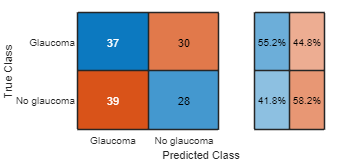

distance    = string(best_values.Distance);
standardize = strcmp(best_values.Standardize, 'true');
mdl_final = fitcknn(T_train, 'glaucoma', 'NumNeighbors', n_neighbors, ...
    'Distance', distance, 'Standardize', standardize);

% Pruebas
[Y_pred, scores] = predict(mdl_final, T_test);

% Evaluación del rendimiento del modelo
acc_test_opt = sum(strcmp(Y_pred, T_test.glaucoma)) / height(T_test);


% Visualización de los casos 
figure('Position', [0 0 450 200]);
confusionchart(T_test.glaucoma, Y_pred, 'RowSummary', 'row-normalized')


% Sensibilidad y especificidad
sensitivity = sum(strcmp(Y_pred, 'Glaucoma') & strcmp(T_test.glaucoma, 'Glaucoma')) / sum(strcmp(T_test.glaucoma, 'Glaucoma'));
specificity = sum(strcmp(Y_pred, 'No glaucoma') & strcmp(T_test.glaucoma, 'No glaucoma')) / sum(strcmp(T_test.glaucoma, 'No glaucoma'));

% Exactitud balanceada
balanced_accuracy = (sensitivity + specificity) / 2;
results = [results; table("KNN_opti", mdl_loss, balanced_accuracy, 'VariableNames',{'model','loss','balanced accuracy'})];

% Mostrar resultados
disp(['Accuracy: ', num2str(acc_test_opt)]);

Accuracy: 0.48507


disp(['Balanced Accuracy: ', num2str(balanced_accuracy)]);

Balanced Accuracy: 0.48507


### Entrenamiento de modelo-Classification Trees

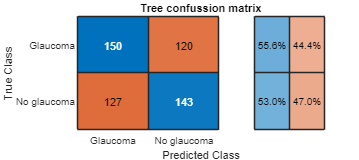

mdl_tree = fitctree(T_train, 'glaucoma', 'CVPartition', cv_in);

mdl_loss = kfoldLoss(mdl_tree);

Y_pred = kfoldPredict(mdl_tree);

sensitivity = sum(strcmp(Y_pred, 'Glaucoma') & strcmp(T_train.glaucoma, 'Glaucoma')) / sum(strcmp(T_train.glaucoma, 'Glaucoma'));
specificity = sum(strcmp(Y_pred, 'No glaucoma') & strcmp(T_train.glaucoma, 'No glaucoma')) / sum(strcmp(T_train.glaucoma, 'No glaucoma'));

% Exactitud balanceada
balanced_accuracy = (sensitivity + specificity) / 2;
results = [results; table("Tree", mdl_loss, balanced_accuracy, 'VariableNames',{'model','loss','balanced accuracy'})];

figure('Position', [0 0 450 200]);
confusionchart(T_train.glaucoma, Y_pred, 'RowSummary','row-normalized')
title('Tree confussion matrix');

### Entrenamiento de modelo-Naive Bayes

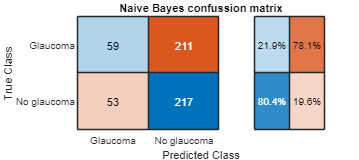

mdl_NB = fitcnb(T_train, 'glaucoma','CVPartition', cv_in);
mdl_loss = kfoldLoss(mdl_NB);
Y_pred = kfoldPredict(mdl_NB);

sensitivity = sum(strcmp(Y_pred, 'Glaucoma') & strcmp(T_train.glaucoma, 'Glaucoma')) / sum(strcmp(T_train.glaucoma, 'Glaucoma'));
specificity = sum(strcmp(Y_pred, 'No glaucoma') & strcmp(T_train.glaucoma, 'No glaucoma')) / sum(strcmp(T_train.glaucoma, 'No glaucoma'));

% Exactitud balanceada
balanced_accuracy = (sensitivity + specificity) / 2;
results = [results; table("Naive_bayes", mdl_loss, balanced_accuracy, 'VariableNames',{'model','loss','balanced accuracy'})];

figure('Position', [0 0 450 200]);
confusionchart(T_train.glaucoma, Y_pred, 'RowSummary','row-normalized')
title('Naive Bayes confussion matrix');

### Entrenamiento de modelo-SVM

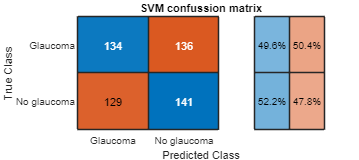

mdl_svm = fitcsvm(T_train, 'glaucoma','CVPartition',cv_in);
mdl_loss = kfoldLoss(mdl_svm);
Y_pred = kfoldPredict(mdl_svm);

figure('Position', [0 0 450 200]);
confusionchart(T_train.glaucoma, Y_pred, 'RowSummary','row-normalized')
title('SVM confussion matrix');


sensitivity = sum(strcmp(Y_pred, 'Glaucoma') & strcmp(T_train.glaucoma, 'Glaucoma')) / sum(strcmp(T_train.glaucoma, 'Glaucoma'));
specificity = sum(strcmp(Y_pred, 'No glaucoma') & strcmp(T_train.glaucoma, 'No glaucoma')) / sum(strcmp(T_train.glaucoma, 'No glaucoma'));

% Exactitud balanceada
balanced_accuracy = (sensitivity + specificity) / 2;
results = [results; table("SVM", mdl_loss, balanced_accuracy, 'VariableNames',{'model','loss','balanced accuracy'})];

results

results = 5×3 table
        model         loss      balanced accuracy
    _____________    _______    _________________

    "Knn"            0.46667         0.53333     
    "KNN_opti"       0.46667         0.48507     
    "Tree"           0.45741         0.54259     
    "Naive_bayes"    0.48889         0.51111     
    "SVM"            0.49074         0.50926     


[~, best_model] = min(results.loss);
results(best_model, :)

ans = 1×3 table
    model      loss      balanced accuracy
    ______    _______    _________________

    "Tree"    0.45741         0.54259     


### Validación inicial de los modelos


% TREE
mdl_final_tree = fitctree(T_train, 'glaucoma');
Y_pred_final_tree = predict(mdl_final_tree, T_test);
loss_final_tree = loss(mdl_final_tree, T_test);
accuracy_final_tree = sum(strcmp(Y_pred_final_tree, T_test.glaucoma)) / height(T_test);

results=table;
results = [results; table("Tree_test", loss_final_tree, accuracy_final_tree, 'VariableNames',{'model','loss','accuracy'})];

disp(['Loss final: ', num2str(loss_final_tree)]);

Loss final: 0.45522


disp(['Accuracy final: ', num2str(accuracy_final_tree)]);

Accuracy final: 0.54478


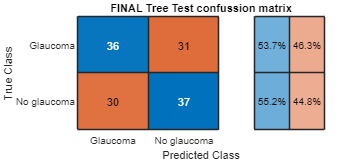


figure('Position', [0 0 450 200]);
confusionchart(T_test.glaucoma, Y_pred_final_tree, 'RowSummary','row-normalized')
title('FINAL Tree Test confussion matrix');


% KNN
mdl_final_knn = fitcknn(T_train, 'glaucoma');
Y_pred_final_knn = predict(mdl_final_knn, T_test);
loss_final_knn = loss(mdl_final_knn, T_test);
accuracy_final_knn = sum(strcmp(Y_pred_final_knn, T_test.glaucoma)) / height(T_test);

disp(['Loss final: ', num2str(loss_final_knn)]);

Loss final: 0.50746


disp(['Accuracy final: ', num2str(accuracy_final_knn)]);

Accuracy final: 0.49254


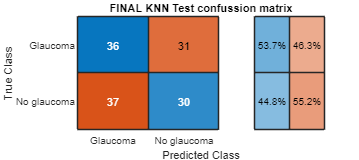


results = [results; table("KNN_test", loss_final_knn, accuracy_final_knn, 'VariableNames',{'model','loss','accuracy'})];

figure('Position', [0 0 450 200]);
confusionchart(T_test.glaucoma, Y_pred_final_knn, 'RowSummary','row-normalized')
title('FINAL KNN Test confussion matrix');


% NB
mdl_final_nb = fitcnb(T_train, 'glaucoma');
Y_pred_final_nb = predict(mdl_final_nb, T_test);
loss_final_nb = loss(mdl_final_nb, T_test);
accuracy_final_nb = sum(strcmp(Y_pred_final_nb, T_test.glaucoma)) / height(T_test);

disp(['Loss final: ', num2str(loss_final_nb)]);

Loss final: 0.47015


disp(['Accuracy final: ', num2str(accuracy_final_nb)]);

Accuracy final: 0.52985


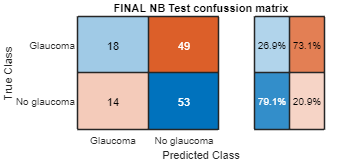

results = [results; table("NB_test", loss_final_nb, accuracy_final_nb, 'VariableNames',{'model','loss','accuracy'})];

figure('Position', [0 0 450 200]);
confusionchart(T_test.glaucoma, Y_pred_final_nb, 'RowSummary','row-normalized')
title('FINAL NB Test confussion matrix');


% SVM
mdl_final_svm = fitcsvm(T_train, 'glaucoma');
Y_pred_final_svm = predict(mdl_final_svm, T_test);
loss_final_svm = loss(mdl_final_svm, T_test);
accuracy_final_svm = sum(strcmp(Y_pred_final_svm, T_test.glaucoma)) / height(T_test);
results = [results; table("SVM_test", loss_final_svm, accuracy_final_svm, 'VariableNames',{'model','loss','accuracy'})];

disp(['Loss final: ', num2str(loss_final_svm)]);

Loss final: 0.5


disp(['Accuracy final: ', num2str(accuracy_final_svm)]);

Accuracy final: 0.5


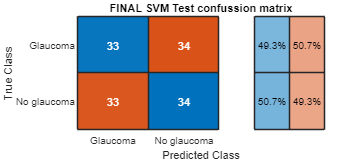


figure('Position', [0 0 450 200]);
confusionchart(T_test.glaucoma, Y_pred_final_svm, 'RowSummary','row-normalized')
title('FINAL SVM Test confussion matrix');

results

results = 4×3 table
       model        loss      accuracy
    ___________    _______    ________

    "Tree_test"    0.45522    0.54478 
    "KNN_test"     0.50746    0.49254 
    "NB_test"      0.47015    0.52985 
    "SVM_test"         0.5        0.5 


### Validación con los eliminados y balanceado 

 Se han entrenado con el T_Train anterior (proveniente de la base de datos balanceada) y se han incluido las imagenes eliminadas al T_Test

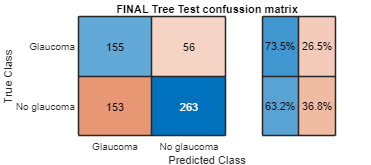

results=table; 
% Leer los índices eliminados desde el archivo CSV
indices_eliminados = readmatrix('indices_eliminados.csv');
T_original = readtable("Caracteristicas_MODELO_actualizado.csv");

% Recuperar las imágenes eliminadas de "No glaucoma"
imagenes_recuperadas = T_original(indices_eliminados, :);

% Convertir la columna glaucoma a numérico si es necesario

imagenes_recuperadas.glaucoma = cellstr(num2str(imagenes_recuperadas.glaucoma));

 for i = 1:height(imagenes_recuperadas)
    if imagenes_recuperadas.glaucoma{i} == '1'
        imagenes_recuperadas.glaucoma{i} = 'Glaucoma';
    elseif imagenes_recuperadas.glaucoma{i} == '0'
        imagenes_recuperadas.glaucoma{i} = 'No glaucoma';
    end
end

% Combinar las imágenes recuperadas con los datos balanceados
rng(4);
imagenes_recuperadas.image=[];
imagenes_recuperadas.mean_wavelet_1=[];imagenes_recuperadas.mean_wavelet_2=[];imagenes_recuperadas.mean_wavelet_3=[];imagenes_recuperadas.mean_wavelet_4=[];imagenes_recuperadas.mean_wavelet_5=[];imagenes_recuperadas.mean_wavelet_6=[];imagenes_recuperadas.mean_wavelet_7=[];imagenes_recuperadas.mean_wavelet_8=[];imagenes_recuperadas.mean_wavelet_9=[];imagenes_recuperadas.mean_wavelet_10=[];
imagenes_recuperadas.variance_wavelet_1=[];imagenes_recuperadas.variance_wavelet_2=[];imagenes_recuperadas.variance_wavelet_3=[];imagenes_recuperadas.variance_wavelet_4=[];imagenes_recuperadas.variance_wavelet_5=[];imagenes_recuperadas.variance_wavelet_6=[];imagenes_recuperadas.variance_wavelet_7=[];imagenes_recuperadas.variance_wavelet_8=[];imagenes_recuperadas.variance_wavelet_9=[];imagenes_recuperadas.variance_wavelet_10=[];
imagenes_recuperadas.energy_wavelet_1=[];imagenes_recuperadas.energy_wavelet_2=[];imagenes_recuperadas.energy_wavelet_3=[];imagenes_recuperadas.energy_wavelet_4=[];imagenes_recuperadas.energy_wavelet_5=[];imagenes_recuperadas.energy_wavelet_6=[];imagenes_recuperadas.energy_wavelet_7=[];imagenes_recuperadas.energy_wavelet_8=[];imagenes_recuperadas.energy_wavelet_9=[];imagenes_recuperadas.energy_wavelet_10=[];


updated_data_test = [T_test; imagenes_recuperadas];

% Test final TREE
mdl_final_tree = fitctree(T_train, 'glaucoma');
Y_pred_final_tree = predict(mdl_final_tree, updated_data_test);
loss_final_tree = loss(mdl_final_tree, updated_data_test);

sensitivity = sum(strcmp(Y_pred_final_tree, 'Glaucoma') & strcmp(updated_data_test.glaucoma, 'Glaucoma')) / sum(strcmp(updated_data_test.glaucoma, 'Glaucoma'));
specificity = sum(strcmp(Y_pred_final_tree, 'No glaucoma') & strcmp(updated_data_test.glaucoma, 'No glaucoma')) / sum(strcmp(updated_data_test.glaucoma, 'No glaucoma'));

% Exactitud balanceada
balanced_accuracy = (sensitivity + specificity) / 2;
results = [results; table("Tree", loss_final_tree, balanced_accuracy, 'VariableNames',{'model','loss','balanced accuracy'})];

figure('Position', [0 0 450 200]);
confusionchart(updated_data_test.glaucoma, Y_pred_final_tree, 'RowSummary','row-normalized')
title('FINAL Tree Test confussion matrix');

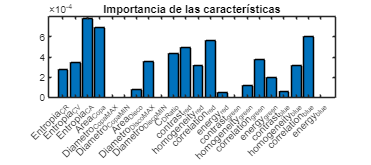


importance = predictorImportance(mdl_final_tree);
bar(importance);
xticklabels({'Entropia_CR','Entropia_CV','Entropia_CA','Area_Copa','Diametro_Copa_MAX','Diametro_Copa_MIN','Area_Disco','Diametro_Disco_MAX','Diametro_Disco_MIN','C_DRatio','contrast_red','homogeneity_red','correlation_red','energy_red','contrast_green','homogeneity_green','correlation_green','energy_green','contrast_blue','homogeneity_blue','correlation_blue','energy_blue'});
xticks(1:length(importance));

% Rotar las etiquetas del eje X
xtickangle(45);

% Reducir el tamaño de la fuente
ax = gca;
ax.XAxis.FontSize = 10;
title('Importancia de las características');

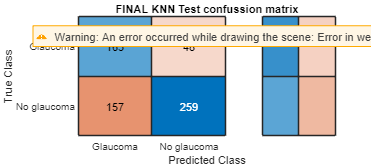

% 
% Visualizar el árbol de decisión
view(mdl_final_tree, 'Mode', 'graph');

% Test final KNN
mdl_final_knn = fitcknn(T_train, 'glaucoma');
Y_pred_final_knn = predict(mdl_final_knn, updated_data_test);
loss_final_knn = loss(mdl_final_knn, updated_data_test);

sensitivity = sum(strcmp(Y_pred_final_knn, 'Glaucoma') & strcmp(updated_data_test.glaucoma, 'Glaucoma')) / sum(strcmp(updated_data_test.glaucoma, 'Glaucoma'));
specificity = sum(strcmp(Y_pred_final_knn, 'No glaucoma') & strcmp(updated_data_test.glaucoma, 'No glaucoma')) / sum(strcmp(updated_data_test.glaucoma, 'No glaucoma'));

% Exactitud balanceada
balanced_accuracy = (sensitivity + specificity) / 2;
results = [results; table("KNN", loss_final_knn, balanced_accuracy, 'VariableNames',{'model','loss','balanced accuracy'})];

figure('Position', [0 0 450 200]);
confusionchart(updated_data_test.glaucoma, Y_pred_final_knn, 'RowSummary','row-normalized')
title('FINAL KNN Test confussion matrix');

results

results = 2×3 table
    model      loss      balanced accuracy
    ______    _______    _________________

    "Tree"     0.3166          0.6834     
    "KNN"     0.30245         0.69755     


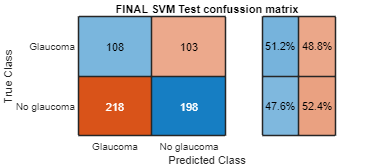


% Test final SVM
mdl_final_svm = fitcsvm(T_train, 'glaucoma');
Y_pred_final_svm = predict(mdl_final_svm, updated_data_test);
loss_final_svm = loss(mdl_final_svm, updated_data_test);

sensitivity = sum(strcmp(Y_pred_final_svm, 'Glaucoma') & strcmp(updated_data_test.glaucoma, 'Glaucoma')) / sum(strcmp(updated_data_test.glaucoma, 'Glaucoma'));
specificity = sum(strcmp(Y_pred_final_svm, 'No glaucoma') & strcmp(updated_data_test.glaucoma, 'No glaucoma')) / sum(strcmp(updated_data_test.glaucoma, 'No glaucoma'));

% Exactitud balanceada
balanced_accuracy = (sensitivity + specificity) / 2;
results = [results; table("SVM", loss_final_svm, balanced_accuracy, 'VariableNames',{'model','loss','balanced accuracy'})];

figure('Position', [0 0 450 200]);
confusionchart(updated_data_test.glaucoma, Y_pred_final_svm, 'RowSummary','row-normalized')
title('FINAL SVM Test confussion matrix');

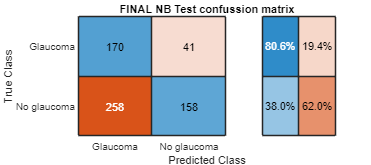


% % Eliminar características con varianza cero
% zeroVarIdx = varfun(@(x) var(x) == 0, updated_data_train, 'InputVariables', @isnumeric);
% zeroVarCols = updated_data_train.Properties.VariableNames(zeroVarIdx{1, :});
% updated_data_train = removevars(updated_data_train, zeroVarCols);
% updated_data_test = removevars(updated_data_test, zeroVarCols);

% Test final NB
% mdl_final_nb = fitcnb(updated_data_train, 'glaucoma');
mdl_final_nb=fitcnb(T_train, 'glaucoma', 'DistributionNames', 'kernel');
Y_pred_final_nb = predict(mdl_final_nb, updated_data_test);
loss_final_nb = loss(mdl_final_nb, updated_data_test);

sensitivity = sum(strcmp(Y_pred_final_nb, 'Glaucoma') & strcmp(updated_data_test.glaucoma, 'Glaucoma')) / sum(strcmp(updated_data_test.glaucoma, 'Glaucoma'));
specificity = sum(strcmp(Y_pred_final_nb, 'No glaucoma') & strcmp(updated_data_test.glaucoma, 'No glaucoma')) / sum(strcmp(updated_data_test.glaucoma, 'No glaucoma'));

% Exactitud balanceada
balanced_accuracy = (sensitivity + specificity) / 2;
results = [results; table("NB", loss_final_nb, balanced_accuracy, 'VariableNames',{'model','loss','balanced accuracy'})];

figure('Position', [0 0 450 200]);
confusionchart(updated_data_test.glaucoma, Y_pred_final_nb, 'RowSummary','row-normalized')
title('FINAL NB Test confussion matrix');


results

results = 4×3 table
    model      loss      balanced accuracy
    ______    _______    _________________

    "Tree"     0.3166          0.6834     
    "KNN"     0.30245         0.69755     
    "SVM"      0.5061          0.4939     
    "NB"      0.40725         0.59275     


[~, best_model] = min(results.loss);
results(best_model, :)

ans = 1×3 table
    model     loss      balanced accuracy
    _____    _______    _________________

    "KNN"    0.30245         0.69755     


### Validación con los eliminados y sin balancear

En esta sección se han incorporado las imagenes eliminadas tanto en el T_train como en el T_test tras recibir una partición, con el objetivo de mantener mismo peso entre particiones. 

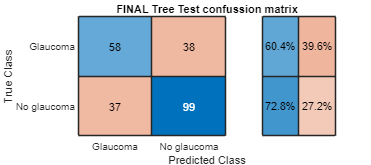

results=table; 
% Leer los índices eliminados desde el archivo CSV
indices_eliminados = readmatrix('indices_eliminados.csv');
T_original = readtable("Caracteristicas_MODELO_actualizado.csv");

% Recuperar las imágenes eliminadas de "No glaucoma"
imagenes_recuperadas = T_original(indices_eliminados, :);

% Convertir la columna glaucoma a numérico si es necesario

imagenes_recuperadas.glaucoma = cellstr(num2str(imagenes_recuperadas.glaucoma));

 for i = 1:height(imagenes_recuperadas)
    if imagenes_recuperadas.glaucoma{i} == '1'
        imagenes_recuperadas.glaucoma{i} = 'Glaucoma';
    elseif imagenes_recuperadas.glaucoma{i} == '0'
        imagenes_recuperadas.glaucoma{i} = 'No glaucoma';
    end
end

% Combinar las imágenes recuperadas con los datos balanceados
rng(4);
imagenes_recuperadas.image=[];
imagenes_recuperadas.mean_wavelet_1=[];imagenes_recuperadas.mean_wavelet_2=[];imagenes_recuperadas.mean_wavelet_3=[];imagenes_recuperadas.mean_wavelet_4=[];imagenes_recuperadas.mean_wavelet_5=[];imagenes_recuperadas.mean_wavelet_6=[];imagenes_recuperadas.mean_wavelet_7=[];imagenes_recuperadas.mean_wavelet_8=[];imagenes_recuperadas.mean_wavelet_9=[];imagenes_recuperadas.mean_wavelet_10=[];
imagenes_recuperadas.variance_wavelet_1=[];imagenes_recuperadas.variance_wavelet_2=[];imagenes_recuperadas.variance_wavelet_3=[];imagenes_recuperadas.variance_wavelet_4=[];imagenes_recuperadas.variance_wavelet_5=[];imagenes_recuperadas.variance_wavelet_6=[];imagenes_recuperadas.variance_wavelet_7=[];imagenes_recuperadas.variance_wavelet_8=[];imagenes_recuperadas.variance_wavelet_9=[];imagenes_recuperadas.variance_wavelet_10=[];
imagenes_recuperadas.energy_wavelet_1=[];imagenes_recuperadas.energy_wavelet_2=[];imagenes_recuperadas.energy_wavelet_3=[];imagenes_recuperadas.energy_wavelet_4=[];imagenes_recuperadas.energy_wavelet_5=[];imagenes_recuperadas.energy_wavelet_6=[];imagenes_recuperadas.energy_wavelet_7=[];imagenes_recuperadas.energy_wavelet_8=[];imagenes_recuperadas.energy_wavelet_9=[];imagenes_recuperadas.energy_wavelet_10=[];

p = 0.2;
cv_out = cvpartition(imagenes_recuperadas.glaucoma, 'HoldOut', p, 'Stratify', true);
T_train_recuperada = imagenes_recuperadas(cv_out.training, :);
T_test_recuperada   = imagenes_recuperadas(cv_out.test, :);

updated_data_train = [T_train; T_train_recuperada];
updated_data_test = [T_test; T_test_recuperada];

% Test final con el mejor modelo
mdl_final_tree = fitctree(updated_data_train, 'glaucoma');
Y_pred_final_tree = predict(mdl_final_tree, updated_data_test);
loss_final_tree = loss(mdl_final_tree, updated_data_test);

sensitivity = sum(strcmp(Y_pred_final_tree, 'Glaucoma') & strcmp(updated_data_test.glaucoma, 'Glaucoma')) / sum(strcmp(updated_data_test.glaucoma, 'Glaucoma'));
specificity = sum(strcmp(Y_pred_final_tree, 'No glaucoma') & strcmp(updated_data_test.glaucoma, 'No glaucoma')) / sum(strcmp(updated_data_test.glaucoma, 'No glaucoma'));

% Exactitud balanceada
balanced_accuracy = (sensitivity + specificity) / 2;
results = [results; table("Tree", loss_final_tree, balanced_accuracy, 'VariableNames',{'model','loss','balanced accuracy'})];

figure('Position', [0 0 450 200]);
confusionchart(updated_data_test.glaucoma, Y_pred_final_tree, 'RowSummary','row-normalized')
title('FINAL Tree Test confussion matrix');

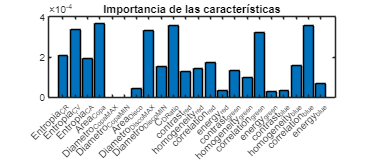


importance = predictorImportance(mdl_final_tree);
bar(importance);
xticklabels({'Entropia_CR','Entropia_CV','Entropia_CA','Area_Copa','Diametro_Copa_MAX','Diametro_Copa_MIN','Area_Disco','Diametro_Disco_MAX','Diametro_Disco_MIN','C_DRatio','contrast_red','homogeneity_red','correlation_red','energy_red','contrast_green','homogeneity_green','correlation_green','energy_green','contrast_blue','homogeneity_blue','correlation_blue','energy_blue'});
xticks(1:length(importance));

% Rotar las etiquetas del eje X
xtickangle(45);

% Reducir el tamaño de la fuente
ax = gca;
ax.XAxis.FontSize = 10;
title('Importancia de las características');

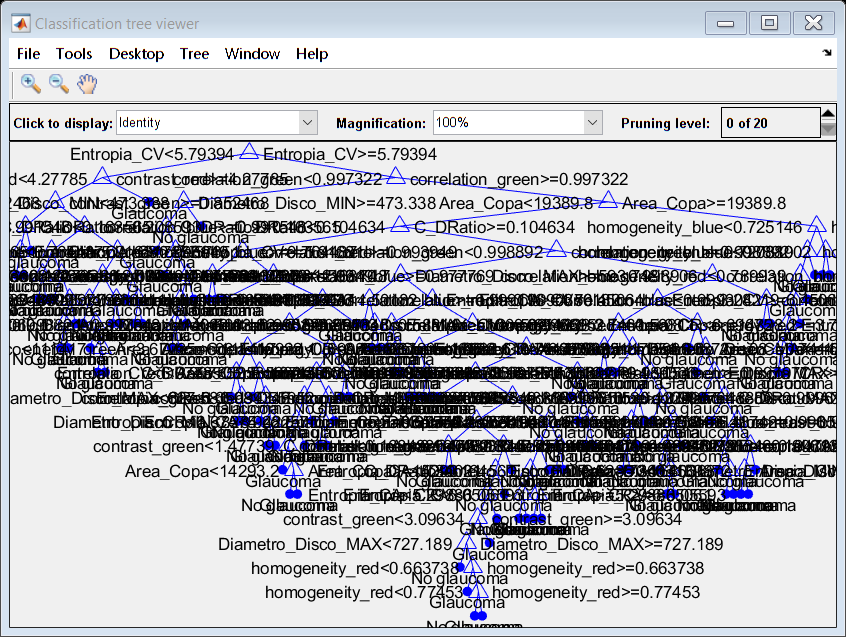

% 
% Visualizar el árbol de decisión
view(mdl_final_tree, 'Mode', 'graph');

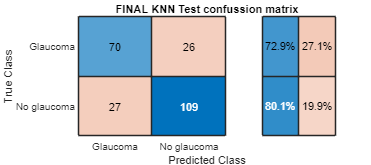


% Test final con el mejor modelo
mdl_final_knn = fitcknn(updated_data_train, 'glaucoma');
Y_pred_final_knn = predict(mdl_final_knn, updated_data_test);
loss_final_knn = loss(mdl_final_knn, updated_data_test);

sensitivity = sum(strcmp(Y_pred_final_knn, 'Glaucoma') & strcmp(updated_data_test.glaucoma, 'Glaucoma')) / sum(strcmp(updated_data_test.glaucoma, 'Glaucoma'));
specificity = sum(strcmp(Y_pred_final_knn, 'No glaucoma') & strcmp(updated_data_test.glaucoma, 'No glaucoma')) / sum(strcmp(updated_data_test.glaucoma, 'No glaucoma'));

% Exactitud balanceada
balanced_accuracy = (sensitivity + specificity) / 2;
results = [results; table("KNN", loss_final_knn, balanced_accuracy, 'VariableNames',{'model','loss','balanced accuracy'})];

figure('Position', [0 0 450 200]);
confusionchart(updated_data_test.glaucoma, Y_pred_final_knn, 'RowSummary','row-normalized')
title('FINAL KNN Test confussion matrix');

results

results = 2×3 table
    model      loss      balanced accuracy
    ______    _______    _________________

    "Tree"    0.32302         0.66605     
    "KNN"      0.2283         0.76532     


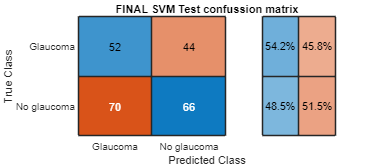


% Test final con el mejor modelo
mdl_final_svm = fitcsvm(updated_data_train, 'glaucoma');
Y_pred_final_svm = predict(mdl_final_svm, updated_data_test);
loss_final_svm = loss(mdl_final_svm, updated_data_test);

sensitivity = sum(strcmp(Y_pred_final_svm, 'Glaucoma') & strcmp(updated_data_test.glaucoma, 'Glaucoma')) / sum(strcmp(updated_data_test.glaucoma, 'Glaucoma'));
specificity = sum(strcmp(Y_pred_final_svm, 'No glaucoma') & strcmp(updated_data_test.glaucoma, 'No glaucoma')) / sum(strcmp(updated_data_test.glaucoma, 'No glaucoma'));

% Exactitud balanceada
balanced_accuracy = (sensitivity + specificity) / 2;
results = [results; table("SVM", loss_final_svm, balanced_accuracy, 'VariableNames',{'model','loss','balanced accuracy'})];

figure('Position', [0 0 450 200]);
confusionchart(updated_data_test.glaucoma, Y_pred_final_svm, 'RowSummary','row-normalized')
title('FINAL SVM Test confussion matrix');

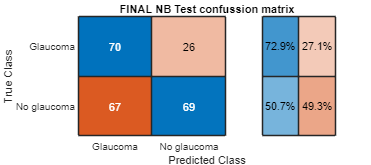


% % Eliminar características con varianza cero
% zeroVarIdx = varfun(@(x) var(x) == 0, updated_data_train, 'InputVariables', @isnumeric);
% zeroVarCols = updated_data_train.Properties.VariableNames(zeroVarIdx{1, :});
% updated_data_train = removevars(updated_data_train, zeroVarCols);
% updated_data_test = removevars(updated_data_test, zeroVarCols);

% Test final con el mejor modelo
% mdl_final_nb = fitcnb(updated_data_train, 'glaucoma');
mdl_final_nb=fitcnb(updated_data_train, 'glaucoma', 'DistributionNames', 'kernel');
Y_pred_final_nb = predict(mdl_final_nb, updated_data_test);
loss_final_nb = loss(mdl_final_nb, updated_data_test);

sensitivity = sum(strcmp(Y_pred_final_nb, 'Glaucoma') & strcmp(updated_data_test.glaucoma, 'Glaucoma')) / sum(strcmp(updated_data_test.glaucoma, 'Glaucoma'));
specificity = sum(strcmp(Y_pred_final_nb, 'No glaucoma') & strcmp(updated_data_test.glaucoma, 'No glaucoma')) / sum(strcmp(updated_data_test.glaucoma, 'No glaucoma'));

% Exactitud balanceada
balanced_accuracy = (sensitivity + specificity) / 2;
results = [results; table("NB", loss_final_nb, balanced_accuracy, 'VariableNames',{'model','loss','balanced accuracy'})];

figure('Position', [0 0 450 200]);
confusionchart(updated_data_test.glaucoma, Y_pred_final_nb, 'RowSummary','row-normalized')
title('FINAL NB Test confussion matrix');


results

results = 4×3 table
    model      loss      balanced accuracy
    ______    _______    _________________

    "Tree"    0.32302         0.66605     
    "KNN"      0.2283         0.76532     
    "SVM"     0.49149         0.51348     
    "NB"      0.40131         0.61826     


[~, best_model] = min(results.loss);
results(best_model, :)

ans = 1×3 table
    model     loss     balanced accuracy
    _____    ______    _________________

    "KNN"    0.2283         0.76532     
